cp_max = C_p_opt

cp_max = 0.4890

rho = 1.2225;
% R_WTR = 1
% P_mppt_sl = 0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_sl^3 %
% P_mppt_max = 15e6;0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_n^3

P_mppt_sl = 0.5*pi*rho*R_WTR*cp_max*v_w_wrated^3 %

P_mppt_sl = 1.2812e+05

P_mppt_max = 0.5*pi*rho*R_WTR*cp_max*v_w_n^3 %0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_n^3

P_mppt_max = 1.3048e+05


slope = (P_mppt_max-P_mppt_sl)/(omega_WTR_n*1.0236-omega_WTR_n)

slope = 1.2632e+05

b = P_mppt_max-slope*omega_WTR_n*1.0235

b = 2.8130e+04


omega_WTR = linspace(0.5,1.2,1000); %*2*pi/60; % rad/s
wind_speed = linspace(8,12,1000);
TS_new = omega_WTR*R_WTR/lambda_opt

TS_new =     6.6477    6.6570    6.6664    6.6757    6.6850    6.6943    6.7036    6.7129    6.7223    6.7316    6.7409    6.7502    6.7595    6.7688    6.7782    6.7875    6.7968    6.8061    6.8154    6.8247    6.8340    6.8434    6.8527    6.8620    6.8713    6.8806    6.8899    6.8993    6.9086    6.9179    6.9272    6.9365    6.9458    6.9552    6.9645    6.9738    6.9831    6.9924    7.0017    7.0111    7.0204    7.0297    7.0390    7.0483    7.0576    7.0670    7.0763    7.0856    7.0949    7.1042



Cp_new = interp1(TSRvector,Powercoefficient(:,6),TS_new,"pchip")

Cp_new =     0.4130    0.4136    0.4141    0.4146    0.4152    0.4157    0.4162    0.4168    0.4173    0.4178    0.4183    0.4188    0.4194    0.4199    0.4204    0.4209    0.4214    0.4219    0.4224    0.4229    0.4234    0.4239    0.4243    0.4248    0.4253    0.4258    0.4263    0.4267    0.4272    0.4276    0.4281    0.4286    0.4290    0.4295    0.4299    0.4303    0.4308    0.4312    0.4316    0.4321    0.4325    0.4329    0.4334    0.4338    0.4342    0.4346    0.4350    0.4354    0.4359    0.4363


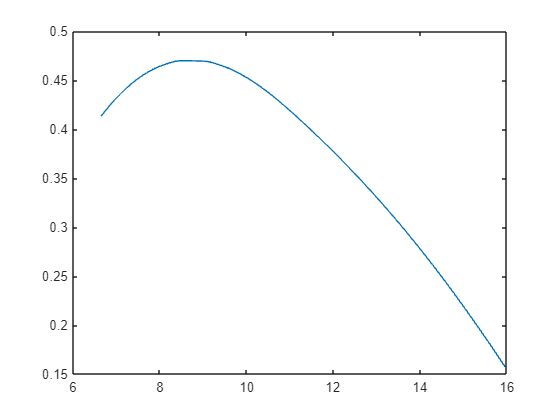

plot(TS_new,Cp_new)



y = zeros(size(omega_WTR));
for i = 1:length(y)
if omega_WTR(i) < omega_WTR_min
    y(i) = 0;
elseif omega_WTR(i) < omega_WTR_sl
    y(i) = 0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR(i)^3;
elseif omega_WTR(i) < omega_WTR_n
    y(i) = slope*omega_WTR(i)+b;
    % omega_WTR_n*1.0236*R_WTR/v_w_n;
    % lambda_not_opt = 15;%TSRvector(15)
    % cp_zero_deg = Powercoefficient(15,6);
    % y(i) = 0.5*pi*rho*R_WTR^5*0.4695/8.722^3*omega_WTR(i)^3;
else
    y(i) = 15e6;%0.5*pi*rho*R_WTR^2*cp_max*v_w_n^3;
     % y(i) = slope*omega_WTR(i)+b;
end
end
omega_WTR(find(y>15e6,1))


ans =

  1×0 empty double row vector



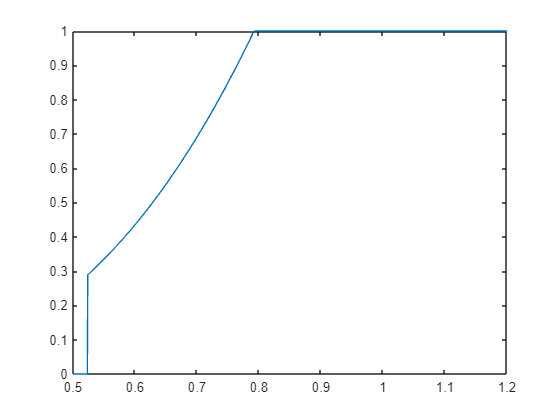

plot(omega_WTR,y/15e6)

## CP

Powercoefficient

Powercoefficient =     0.0073    0.0094    0.0115    0.0138    0.0160    0.0184    0.0207    0.0232    0.0256    0.0281    0.0307    0.0332    0.0357    0.0383    0.0407    0.0432    0.0456    0.0478    0.0499    0.0519    0.0537    0.0552    0.0565    0.0575    0.0582    0.0585    0.0585    0.0582    0.0575    0.0565    0.0551    0.0534    0.0514    0.0491    0.0465    0.0437
    0.0194    0.0235    0.0276    0.0317    0.0359    0.0401    0.0443    0.0485    0.0527    0.0567    0.0607    0.0646    0.0682    0.0716    0.0747    0.0775    0.0798    0.0817    0.0831    0.0840    0.0843    0.0841    0.0832    0.0818    0.0799    0.0774    0.0745    0.0710    0.0672    0.0631    0.0586    0.0538    0.0488    0.0435    0.0380    0.0324
    0.0409    0.0474    0.0539    0.0603    0.0667    0.0730    0.0791    0.0850    0.0907    0.0959    0.1007    0.1050    0.1086    0.1115    0.1137    0.1150    0.1155    0.1151    0.1137    0.1116    0.1086    0.1048    0.1004    0.0953    0.0898    0.083

Pitchanglevector

Pitchanglevector =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


TSRvector

TSRvector =     2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000


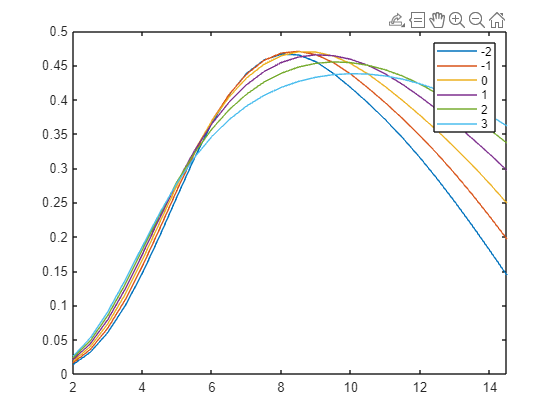

for i = 4:9
    plot(TSRvector,Powercoefficient(:,i))
    hold on
end
hold off
ylim([0 0.5])
xlim([2 14.5])
legend(string(Pitchanglevector(4:9)))


max(max(Powercoefficient))

ans = 0.4704